# The impact of diabetes on blood sugar and insulin levels

This livescript is a brief manual in support of the app ***diabetes_control101.mlapp***.   This is a simple interface to illustrate the relevance of control to medicine and disease management.  increasing numbers of people suffer from diabetes and need medical interventions to manage the condition. The most common treatment is an injection and short time before meals, but this is very crude and does not always lead to good management of blood sugar levels.

In more recent years moves have been made to introduced automated control whereby the patient has a continuous blood sugar monitor and a small pump which supplies insulin directly into the blood stream. This automated system should lead to better control and, critically, avoid the large peaks which can very damaging to health. In a similar way, a feedback loop supplying glucose could be useful to prevent scenarios where an overlarge injection of insulin could cause large drops in blood sugar and even death!

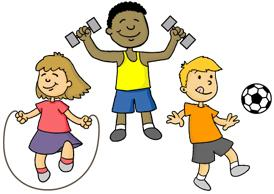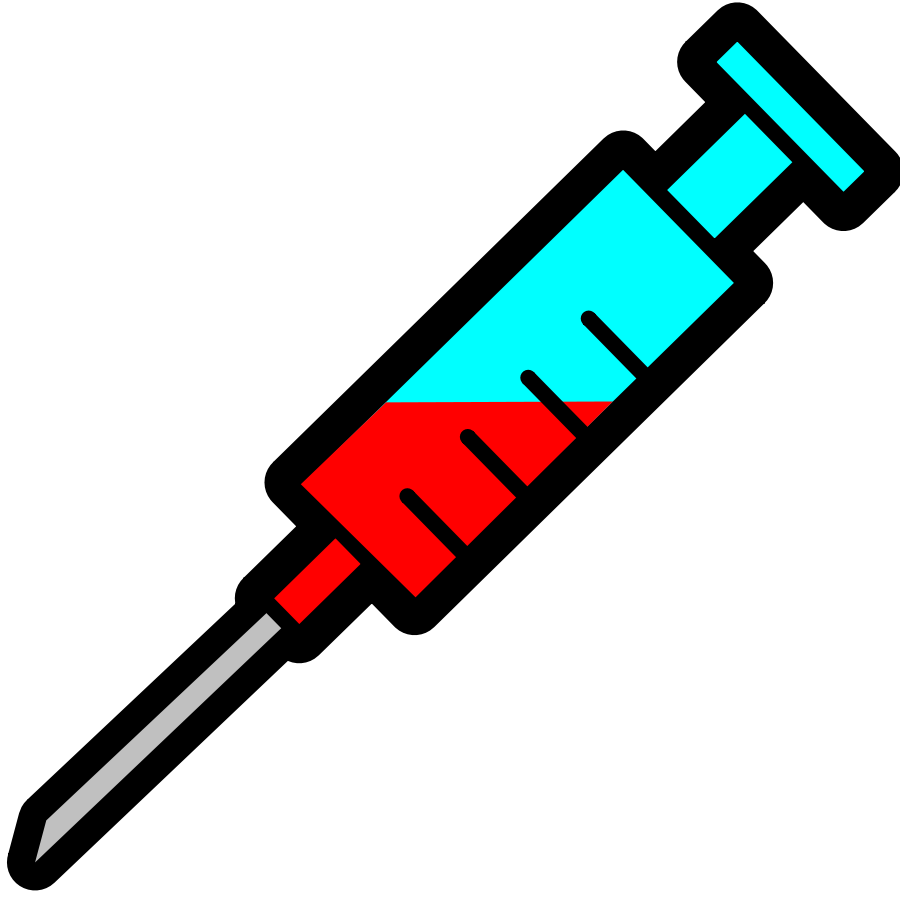   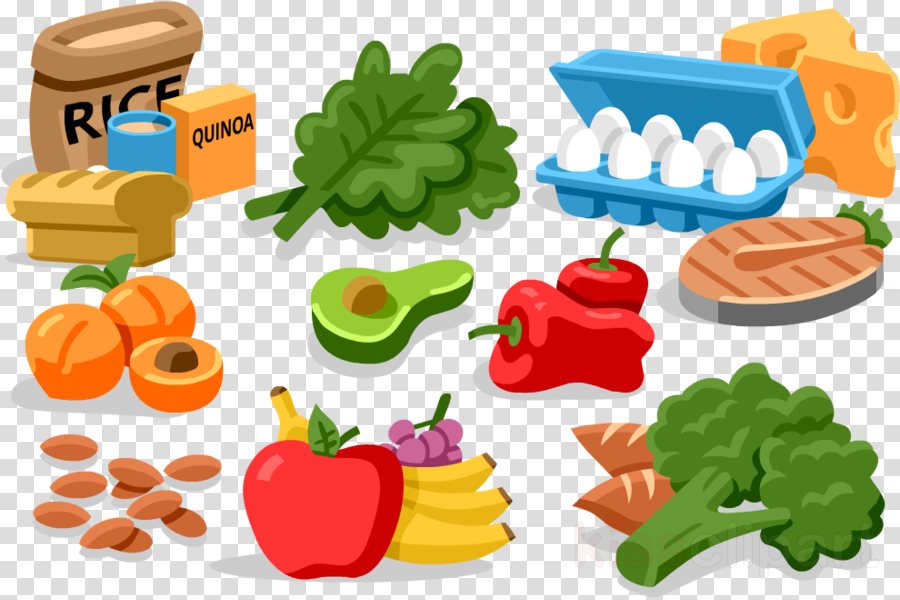

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/section-6-11-community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files uncomment and run either line of the code below:**

%  For documentation in a separate window type one of these 
%        Control101
%        doc Control101 Toolbox (pre 2024 only)
%        doc ("Control101 Toolbox")  
%        doc control101_toolbox. 
%  
%        help control101         (opens within the command window)

File written by:

 J.A.Rossiter, University of Sheffield                         

## Table of contents

- Medical context

- Background on auto-tuning methods

- Interface and user interaction

## 1. Medical context

This app adopts a very simple model for the insulin and glucose levels in the blood:


$$\frac{d}{\mathrm{dt}}\left\lbrack \begin{array}{c}
x\\
w
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
-a & -b\\
f & -g
\end{array}\right\rbrack \underset{X}{\underbrace{\left\lbrack \begin{array}{c}
x\\
w
\end{array}\right\rbrack } } +\left\lbrack \begin{array}{ccc}
0 & d & m\\
k & 0 & 0
\end{array}\right\rbrack \underset{U}{\underbrace{\left\lbrack \begin{array}{c}
I\\
G\\
E
\end{array}\right\rbrack } } ;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\overset{\ldotp }{X} =\mathrm{AX}+\mathrm{BU}$$


where *x* is the blood sugar level, *w* is the blood insulin level, *I* is the injection of insulin (per sec), *G* is the injection of glucose (per sec) and *E* is an exercise rate. it is noted that even with the external inputs, the body inlcudes naturally linked dependencies, in essence internal feedback loops, which ensure t hat the glucose and insulin levels remain at appropriate levels.

**Remark**: These notes assume deviation variables so that values of *x=0, w=0* correspond to  the desired steady-state.

The challenge occurs when the natural human feedback loops begin to break down due ot a failing pancreas. In this case the body is no longer able to regulate sugar levels, that is diabetes; high sugar levels lead to significant damage elsewhere in the body. Hence the intention is to introduce a feedback loop which constantly monitors the blood sugar level and artificially adds insulin as required.

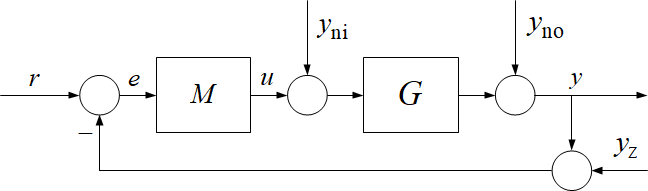

**Figure 1:** Illustration of a feedback loop with external disturbances, system *G* and compensator *M*.

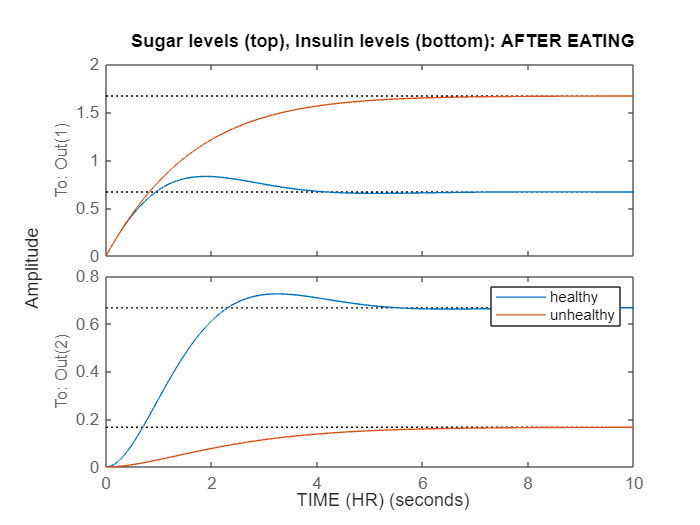

% Healthy person
a=0.5;b=1;f=1;g=1; k=1;d=1;m=1;  
A=[-a -b;f -g];
B  = [0 d -m;k 0 0]; 
C=eye(2);
D = zeros(2,3);
Ghealthy =ss(A,B(:,2),C,D(:,2)); % model with food as input

        
% unhealthy person
a=0.5;b=1;f=0.1;g=1;k=1;d=1;m=1;
A=[-a -b;f -g];
B  = [0 d -m;k 0 0]; 
Gunhealthy =ss(A,B(:,2),C,D(:,2)); % Model with food as input
           
step(Ghealthy,Gunhealthy)
title('Sugar levels (top), Insulin levels (bottom): WHILE EATING')
legend('healthy','unhealthy')
xlabel('time (hr)')

## 2. Control of blood sugar and insulin levels

There are three controls within the model:

- Insulin injections

- Glucose injections

- Exercise

A useful question is to ask whether any of these controls can be used to manage the blood sugar levels better? As this is a theoretical resource, for simplicity it is assumed that all the states are measurable and available for control. A simple control design approach would be LQR, that is the state feedback minimising the following performance index.


$$J=X^T Q\;X+U^T R\;U$$


Regulation control is assumed as the model is taken to be in deviation variables relative to a desired steady-state.

In all cases the inputs can be a combination of controls determined by a feedback law and external (uncontrollable) effects. That is: $U=-K\;X+U_e$. The intention is to maintain the blood sugar at acceptable levels notwithstanding the uncontrollable effects within $U_e$.

The control law takes the form:  $U=-K\;X$and the parameters will depend upon the choices of $Q,R$.

- Use insulin as the control variable and blood sugar as the controlled variable.

- Use glucose as the control variable and blood sugar as the controlled variable.

- Use both insulin and glucose as the control variable and blood sugar as the controlled variable.

**Remark**: It is only possible to 'add' glucose and insulin, thus in cases where an ideal control law would want a negative value, this cannot be supplied. This limitation has a significant impact on achievable performance. In order to implement this in code, it is easier to set the system up as a sampled data system.

% controllers for healthy person
a=0.5;b=1;f=1;g=1; k=1;d=1;m=1;  Tsamp = 0.1;
A=[-a -b;f -g];B  = [0 d -m;k 0 0]; C=eye(2);D = zeros(2,3);
Q =diag([10,1]); R=1;
Ghealthy =ss(A,B,C,D); % model injection to glucose
Gdhealthy = c2d(Ghealthy,Tsamp);  % DISCRETE MODEL
[Adh,Bdh,Cdh,Ddh]=ssdata(Gdhealthy);
Kinsulinh=[dlqr(Adh,Bdh(:,1),Q,R);0 0];  %% fbk law using injection
Kglucoseh=[0 0;dlqr(Adh,Bdh(:,2),Q,R)];  %% fbk law using glucose
app.Kmimoh=dlqr(Adh,Bdh(:,1:2),Q,R);  %% fbk law using both

% controllers for unhealthy person
a=0.5;b=1;f=0.1;g=1;k=1;d=1;m=1;  
A=[-a -b;f -g];B  = [0 d -m;k 0 0]; 
Gunhealthy =ss(A,B,C,D); % model injection to glucose
Gdunhealthy = c2d(Gunhealthy,Tsamp);  % DISCRETE MODEL
[Adh,Bdh,Cdh,Ddh]=ssdata(Gdunhealthy);
Kinsulinu=[dlqr(Adh,Bdh(:,1),Q,R);0 0];  %% fbk law using injection
Kglucoseu=[0 0;dlqr(Adh,Bdh(:,2),Q,R)];  %% fbk law using glucose
app.Kmimou=dlqr(Adh,Bdh(:,1:2),Q,R);  %% fbk law using both

## 3 Closed-loop simulations

This section will be give indicative code only as more comprehensive simulations are available in the app. The purpose here is to show how one can easily investigate performance with the various strategies and scenarios and then plot these. 

**Remark**: Users will note how the control variable cannot go below zero.

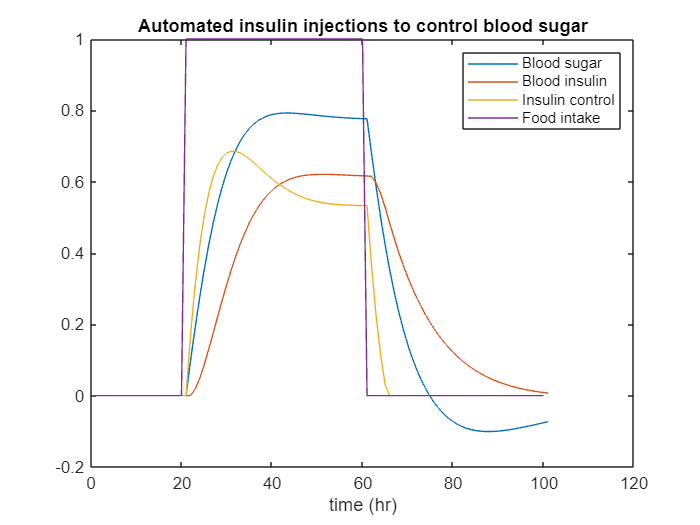

modelchoice=Gdunhealthy;  % choose a model
controlchoice=Kinsulinu;  % choose a compensator
runtime = 100;
disturbance = [0;1;0]*[zeros(1,20),ones(1,40), zeros(1,runtime-60)]; % Food intake

[x,t,u] = simulateclosedloop(modelchoice,controlchoice,disturbance,runtime);
tt=t(1:end-1);
plot(t,x(1,t),t,x(2,t),tt,u(1,tt),tt,disturbance(2,:))
legend('Blood sugar','Blood insulin','Insulin control','Food intake')
xlabel('time (hr)')
title('Automated insulin injections to control blood sugar')

## 4 Using the app file

The app is largely driven by buttons and tabs, but users have limited flexibility in the simulations that can be computed. For example, the underlying models and assumptions are fixed, unlike in the code above where users can change values directly.

The red button options (fbk law and disturbance) are deliberately set so that only one can be used at a time. For more elaborate scenarios use and edit the code in section 3 above.

Two views are available (access views via the tabs) as show in the two figures below.

- Focus on a single scenario and fbk law. [Only 1 disturbance, healthy or unhealthy, one fbk]

- Look at all the scenarios (choice of fbk and disturbance input) simultaneously. This allows a comparison of healthy vs unhealthy persons and the operation for different feedback choices.

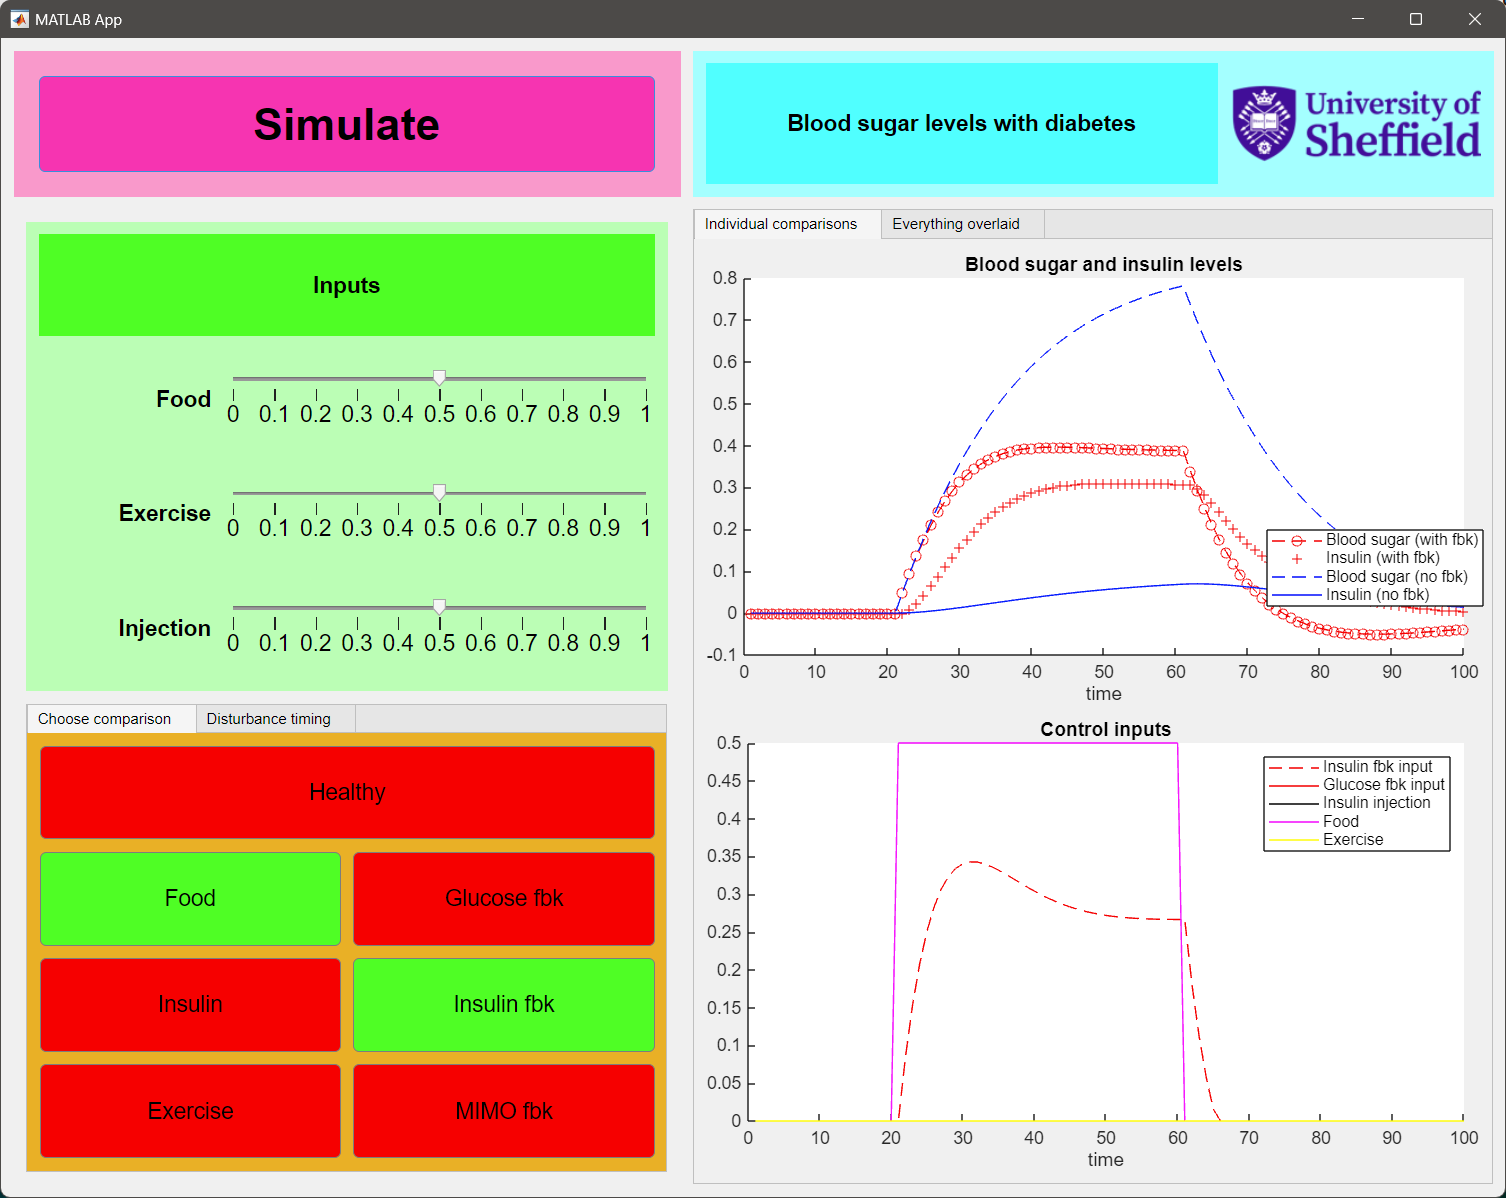

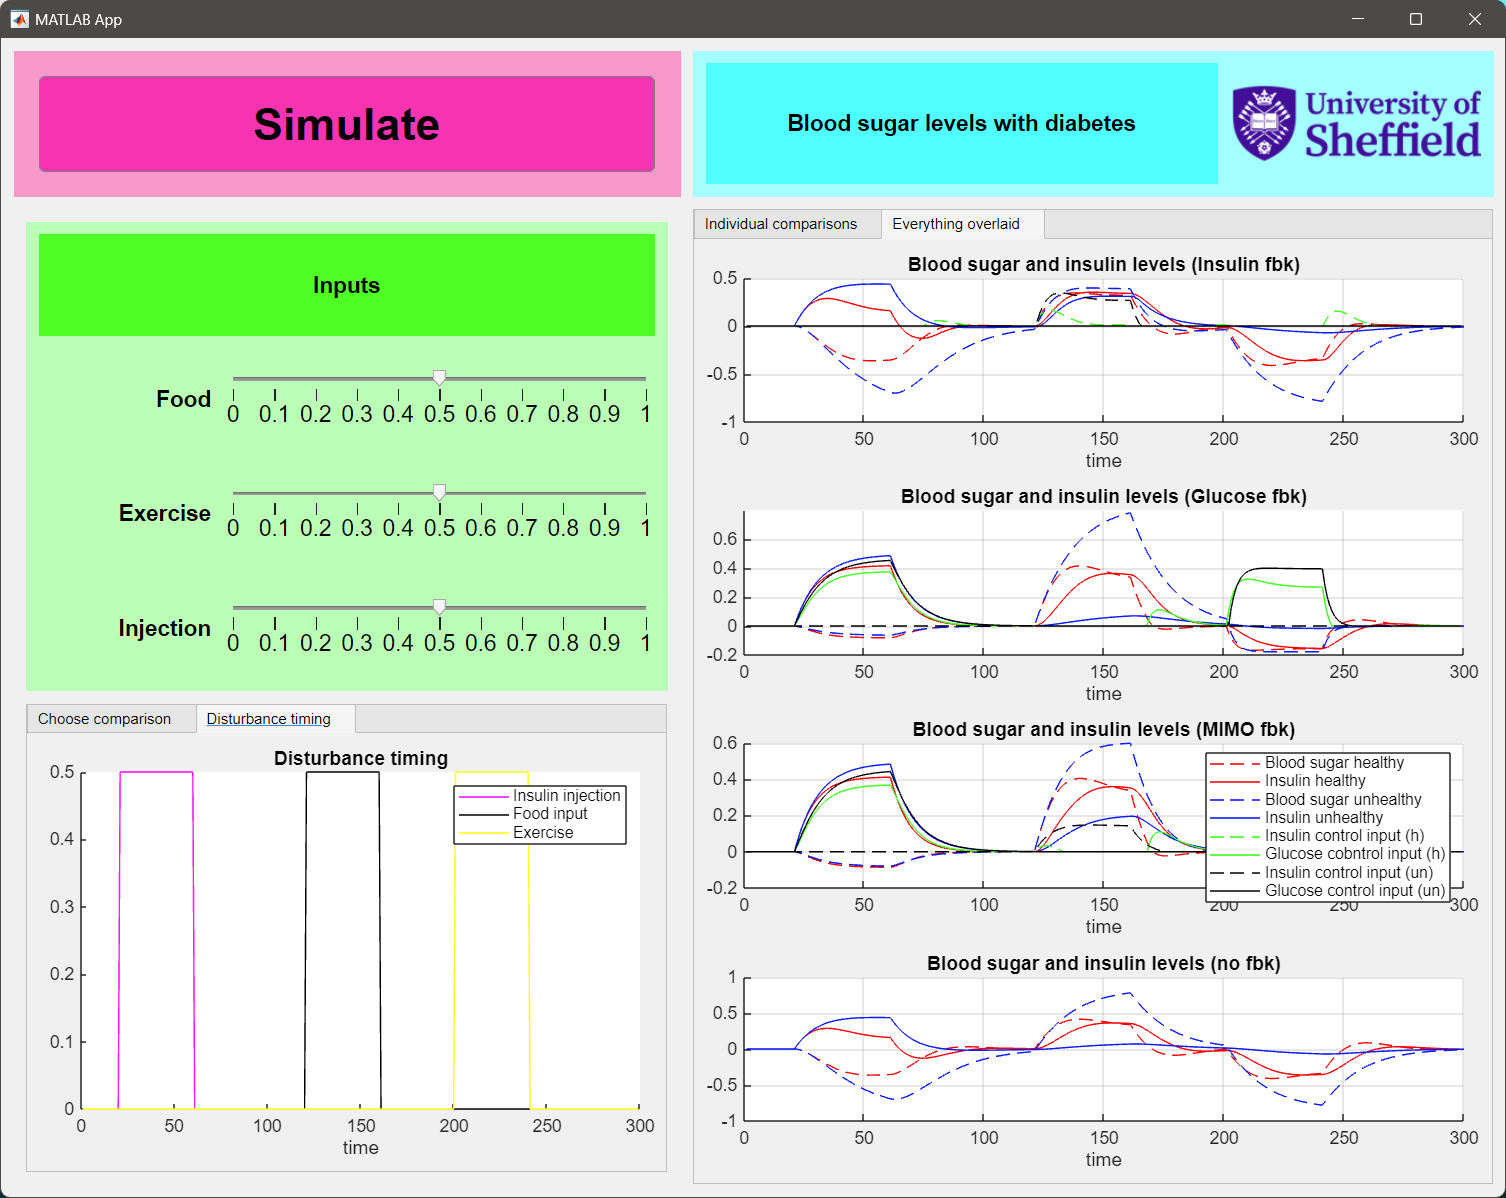

## 5 Useful subfunction for simulation of discrete loops with only positive inputs

function [x,t,ucontrol] = simulateclosedloop(modelchoice,controlchoice,disturbance,runtime)


          [A,B,C,D]=ssdata(modelchoice);
          x=[0;0];ucontrol=[0;0;0];
          tend=runtime; t=1:tend+1;
            for k=1:tend;                

                ucontrol(1,k)=0;
                
              
                ucontrol(1:2,k)=-controlchoice*x(:,k);
                if ucontrol(1,k)<0;ucontrol(1,k)=0;end %% cannot subtract only add
                if ucontrol(2,k)<0;ucontrol(2,k)=0;end %% cannot subtract only add
           
                
                x(:,k+1)=A*x(:,k)+B*ucontrol(:,k)+B*disturbance(:,k);
                

            end  % end of simulation loop
            
            
        end
